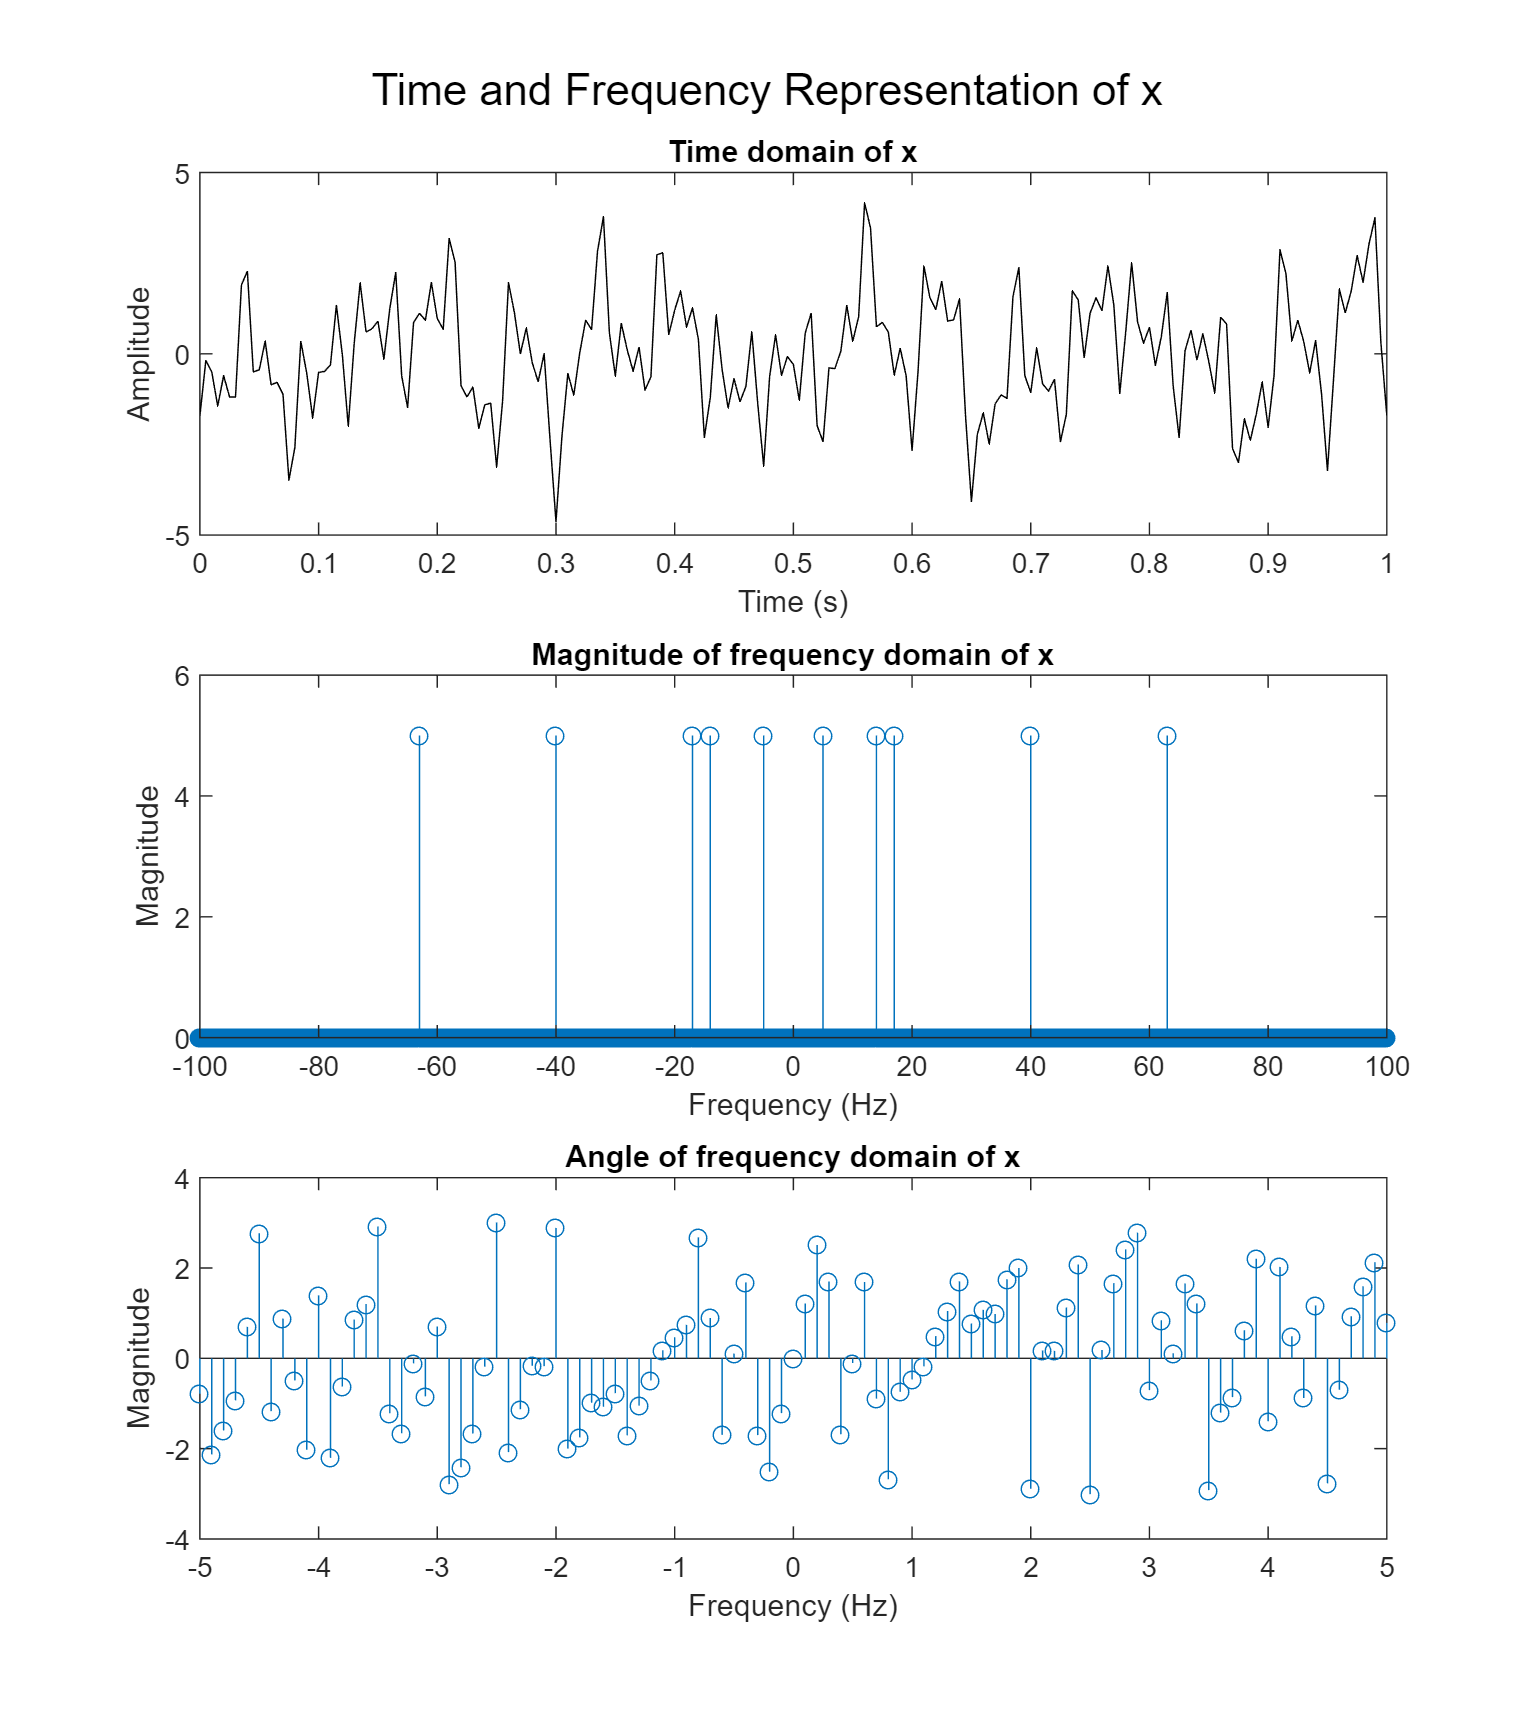

% Week 5 Code challenge
clearvars; close all; clc;

% Note some common variable naming standards:
% Start with lower case letter for time domain signal
% i.e x, y
% Start with Upper case letter for frequency domain signal
% i.e. X, Y

%% Part A
% --- Q1 ---
% Variables

t0 = 0;
T = 10;
samples = 2000;

% Time vector
tA = linspace(t0, t0 + T, samples + 1);
tA(end) = [];

% --- Q2 ---
% Variables
f = [5, 14, 17, 40, 63];
n = 1:length(f);

% Calculate the composite waveform
x = sum(cos(2 * pi * f.' * tA + n.' * pi / 4), 1);

% --- Q3 --- 
% Variables

% Calculate frequency vector
Ts = T / samples;
fsA = 1 / Ts;
fA = linspace(-fsA/2, fsA/2, samples + 1);
fA(end) = [];

% --- Q4 --- 
% Transform to frequency domain

X = fft(x);

% NOTE: Careful to note that if 'x' is a 1 x samples we can fft this straight 
%       up as shown above but if 'a' is a matrix of signals, say 
%       num_signals x samples, we must transpose the matrix so that each signal
%       is on a separate column because the FFT function performs fft columnwise
%       by default.

% --- Q5 --- 
% NOTE: 
% There are sometimes multiple scaling factors used when plotting the
% frequency spectrum of a signal. What does each scaling factor mean?
%   1. Dont scale at all: If the shape of the frequency domain
%       and NOT the amplitude, then sometimes people don't scale their plots.
%       Don't do this in this class (we will mark it wrong) because we want to
%       build good habits for when the amplitude is important.
%   2. Scale by 1/samp: If: the solution to the continuous Fourier Transform
%       is a series of dirac delta functions (i.e. the function in the time 
%       domain is a series of sinusoids, Then: this scaling factor makes the 
%       amplitude of the dirac deltas in the discrete frequency domain equal
%       the area under the dirac deltas in the continuous frequency domain.
%       This is still not correct scaling because dirac deltas have infinite
%       amplitude and it makes no sense to have continuous area = discrete
%       amplitude. (units of V/samp) Don't do this (we will mark it wrong)
%   2. Scale by 1/fs or Ts: Both the signal in the time and frequency
%       domain have constant energy (i.e. maintains Parseval's Theorem). For a
%       signal with dirac deltas in the frequency domain the area of the
%       continuous dirac equals the area of the discrete dirac (amps of
%       discrete impulse*Ts = area of continuous dirac). For other functions
%       the amplitude is correct. units of (V/Hz)


% Plot the signal in the time and frequency domains
figure('units', 'normalized', 'outerposition', [0 0.04 0.5 0.9]), clf
subplot(3,1,1)
plot(tA, x, 'k')
xlabel('Time (s)'), ylabel('Amplitude'), title('Time domain of x')
xlim([0 1])
subplot(3,1,2)

stem(fA, abs(fftshift(X) * Ts))
xlabel('Frequency (Hz)'), ylabel('Magnitude'), title('Magnitude of frequency domain of x')
subplot(3,1,3)

stem(fA, angle(fftshift(X) * Ts))
xlabel('Frequency (Hz)'), ylabel('Magnitude'), title('Angle of frequency domain of x')
xlim([-5 5])
sgtitle('Time and Frequency Representation of x')


% Lets have a closer look at the time domain as it's hard to see what's
% happening

% Save to local disk
% File -> Print to figure -> Save As
% Other options
% path = '.\';
% saveas(gcf,strcat(path, 'Figure'), 'png')

%% Part B

% --- Q1 ---
% Variables

t0 = -50;
T = 100;
samples = 2000;

% Time vector goes from -50 to +50 seconds

tB = linspace(t0, t0 + T, samples + 1);
tB(end) = []

tB =   -50.0000  -49.9500  -49.9000  -49.8500  -49.8000  -49.7500  -49.7000  -49.6500  -49.6000  -49.5500  -49.5000  -49.4500  -49.4000  -49.3500  -49.3000  -49.2500  -49.2000  -49.1500  -49.1000  -49.0500  -49.0000  -48.9500  -48.9000  -48.8500  -48.8000  -48.7500  -48.7000  -48.6500  -48.6000  -48.5500  -48.5000  -48.4500  -48.4000  -48.3500  -48.3000  -48.2500  -48.2000  -48.1500  -48.1000  -48.0500  -48.0000  -47.9500  -47.9000  -47.8500  -47.8000  -47.7500  -47.7000  -47.6500  -47.6000  -47.5500



% --- Q2 --- 
% Variables
fc = 5;

% Generate the signal and its shifted version

y = sinc(tB);
yShift = y .* cos(2 * pi * fc * tB)

yShift =     0.0000   -0.0000    0.0020    0.0000   -0.0038    0.0000    0.0052    0.0000   -0.0061   -0.0000    0.0064    0.0000   -0.0061    0.0000    0.0052   -0.0000   -0.0038   -0.0000    0.0020    0.0000    0.0000    0.0000   -0.0020    0.0000    0.0038    0.0000   -0.0053   -0.0000    0.0062    0.0000   -0.0066    0.0000    0.0063    0.0000   -0.0053    0.0000    0.0039    0.0000   -0.0020    0.0000   -0.0000   -0.0000    0.0021    0.0000   -0.0039    0.0000    0.0054    0.0000   -0.0064   -0.0000



% --- Q3 --- 
% Find sampling frequency to be able to determine the frequency vector
Ts = T / samples;
fs = 1 / Ts;
% Calculate the frequency vector

fB = linspace(-fs / 2, fs / 2, samples + 1);
fB(end) = [];

% --- Q4 --- 
% Transform to frequency domain

Y = fft(y);
YShift = fft(yShift);

% --- Q5 --- 
figure('units', 'normalized', 'outerposition', [0 0.44 1 0.56]), clf
subplot(2,2,1)
plot(tB, y, 'k')

xlim([-5 5])
xlabel('Time (s)'), ylabel('Amplitude'), title('Time domain of y')
subplot(2,2,2)
stem(fB, abs(fftshift(Y) * Ts))

xlim([-6 6])
xlabel('Frequency (Hz)'), ylabel('Magnitude'), title('Magnitude of frequency domain of Y')
subplot(2,2,3)
stem(tB, YShift, 'k')

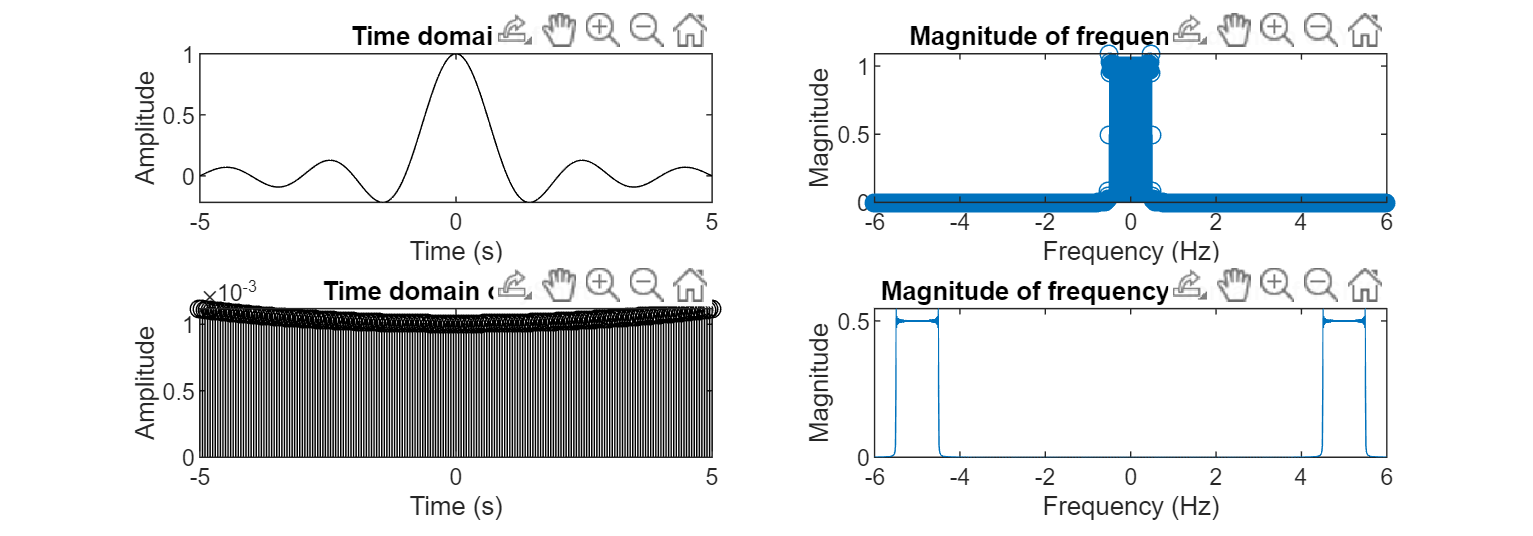


xlim([-5 5])
xlabel('Time (s)'), ylabel('Amplitude'), title('Time domain of yShift')
subplot(2,2,4)
plot(fB, abs(fftshift(YShift) * Ts))

xlim([-6 6])
xlabel('Frequency (Hz)'), ylabel('Magnitude'), title('Magnitude of frequency domain of YShift')